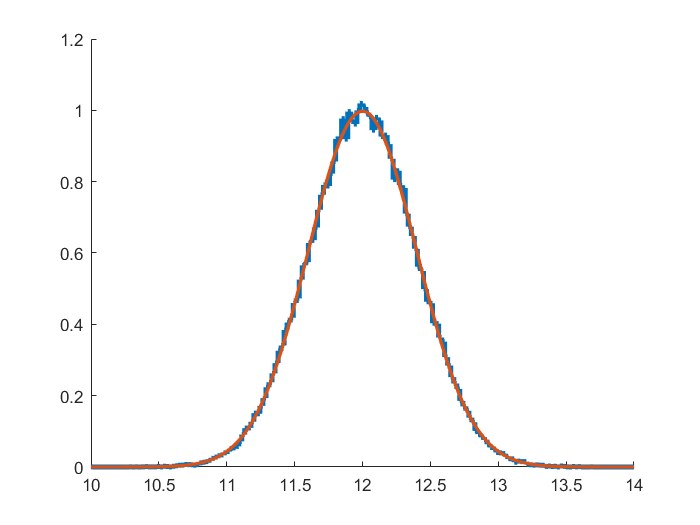

%Lab 3 - Kyle McEleney

%  Problem 1

temp = makedist('Normal', 'mu', 12, 'sigma', 0.4);
data = random(temp, 1, 100000);
outliers = [10, 10.3, 2.1, 0, 0, 15.6, 22.3, 12.7];
full = [data, outliers];
x = linspace(10, 14, 1000);

%A1 Explore with appropriate plots
hold on;
histogram(full, 1000,'DisplayStyle',"stairs",'LineWidth',3, 'normalization', 'pdf')
xlim([10, 14]);
plot(x,pdf(temp,x),"LineWidth",2)
hold off

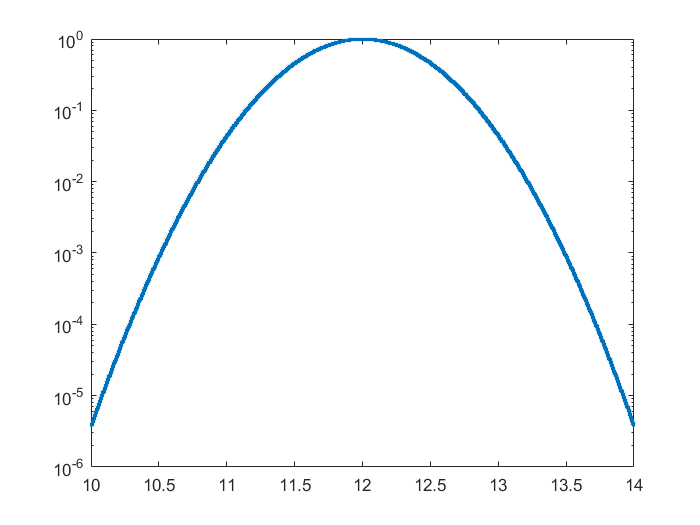

stairs(x,pdf(temp,x),"LineWidth",2);
set(gca,'YScale','log')

%A2 During nominal operation, the temperature is 12 K with an acceptable
%variance of 0.4 K. Is it possible to screen out erroneous readings with
%absolute certainty?

%This question was chosen to provide the basis for a process by which the
%readings coming from the thermal control system are properly screened.
%Doing so allows for proper correlation of the true temperature of the
%experiment with whatever phenomena is being observed.



%A3 If the reading is between 11.6 and 12.4 it is to be included in the
%data set. Otherwise it is to be discarded.


%A4 Apply statistical test, construct truth table
bad_data = [];
good_data = [];
for i=1:100008
    if(full(i) <= 12.4 && full(i) >= 11.6)
        good_data = [good_data, full(i)]; 
    else 
        bad_data = [bad_data, full(i)];   
    end
end

false_negative = 0;
true_positive = 0;
false_positive = 0;
true_negative = 0;

for i=1:length(good_data)
    if(good_data(i) <= 12.4 && good_data(i) >= 11.6)
        true_positive = true_positive + 1;
    else 
        false_negative = false_negative + 1;
    end
end

for i=1:length(bad_data)
    if(bad_data(i) <= 12.4 && bad_data(i) >= 11.6)
        false_positive = false_positive + 1;
    else 
        true_negative = true_negative + 1;
    end
end

True____False = [true_positive, false_positive; true_negative, false_negative];
rownames = {'Pos', 'Neg'};
columnnames = {'true_positive', 'false_positive', 'true_negative', 'false_negative'};

T = table(True____False, 'RowNames', rownames)

T = 2×1 table
           True____False 
           ______________

    Pos    68356        0
    Neg    31652        0


%B How does the number of omissions, where you threw out good data, depend on the statistical threshold you chose and is it a predictable quantity?
% Since the distribution is a random Gaussian, the rigid statistical
% thresholds chosen (+- 0.4 from the mean of 12) allow for a nearly calculable
% quantity of omissions since the inclusive definite integral of the pdf
% using the provided bounds yields the fraction of the total data set which
% will be included (which is a known value in this case).

%C Are there mistakes of commission (bad data getting in)? If yes, are they avoidable and how do they depend on your statistical threshold? 
% No there aren't. Since the bounds are exact, the commission process
% is rigid and precise.



%Problem 2 

%1 If the background distribution of the detected position of a potential
% asteroid is a 2D Gaussian with 1 arcsecond of RMS, what is the 5 sigma
% distance in arcseconds?

%2 The resolution of the histogram is the same in both x and y directions.
% As such, the 2D Guassian centered at 0,0 can be thought of as a 1D
% projection in order to evaluate where the 5 sigma point is located. Since
% the scale of both dimensions is the same, once this point is identified, a
% circle about the mean can be established in order to determine the locate
% the threshold for 5 sigma observations, at which point anything beyond it
% can be considered statistically significant. 

% General form of the 2D Gaussian:



$$f\left(x,y\right)={\mathrm{Ae}}^{-\left(\frac{{\left(x-x_0 \right)}^2 }{2{\sigma_X }^2 }+\frac{{\left(y-y_0 \right)}^2 }{2{\sigma_Y }^2 }\right)}$$



%In this case, x_0 and y_0 are 0, the values of sigma are determined by the
%data set. In order to determine the functional value (f(x,y)) which yields 5 sigma, an integral
%must be taken radially from the origin until it encompasses 5 sigma of the
%data. This value is determined below:




%Problem 3

%1

%2

%3
